# Detección de *blobs* con filtro NLoG

## Importación y limpiado de la imagen

clc, clear, close all;

% Leemos el mapa de bits que sale del microscopio
I = double(imread('../../tiltser_W.tif',6));

% Normalizamos
I = I/max(max(I));

% Recortamos región de la izquierda 
% (Es heurístico pero ayuda a mejorar la calidad de la convolución)
[n,m] = size(I);
I = I(:,9:m);

% Limpiamos el ruido de la imagen con SVD (escogemos menor r posible)
r = 3;
[U,S,V] = svd(I);
If = U(:,1:r)*S(1:r,1:r)*V(:,1:r)';

## Aplicamos el algoritmo

Definimos inicialmente una lista con los sigmas que vamos a utilizar:

sgm_list = [2.0 2.5 3.0 3.5];

Llamamos a la función que aplica el algoritmo de detección de *blobs*:

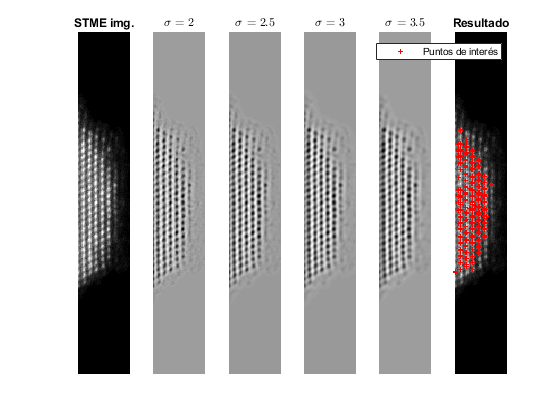

% Para la imagen sin filtrar
blobDetector(I,sgm_list,0.055);

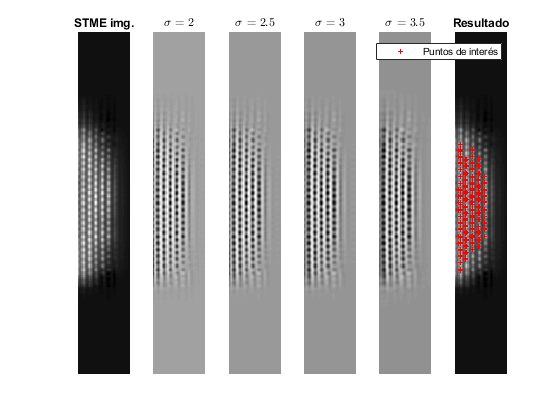


% Para la imagen filtrada
blobDetector(If,sgm_list,0.055);

Actualmente el umbral $\delta
$ se asigna de forma manual. Lo ideal sería poder determinarlo de forma automática en virtud de la calidad de la calidad de la imagen. De este modo el algoritmo sería mucho menos heurístico.

## Algoritmo de detección

function S = blobDetector(I, sgm_list, delta)
    % Inicializamos el tensor S(x,y,sigma)
    N = length(sgm_list); 
    [n,m] = size(I);
    S = zeros(n,m,N);
    
    % Inicializamos la figura con la imagen original
    figure(), clf, subplot(1,N+2,1);
    imagesc(I), axis off
    title("STME img.")
    
    % Generamos grid
    x = linspace(-m, m, m);
    y = linspace(-n, n, n);
    [x,y] = meshgrid(x,y);
    
    % Bucle para los N sigmas
    for i = 1:N
        sigma = sgm_list(i);
        
        % Calculamos NLoG y lo convolucionamos
        NLoG = - 1/pi/sigma^2*(1 - (x.^2 + y.^2)/2/sigma^2).*exp(- (x.^2 + y.^2)/2/sigma^2);
        Iconv = conv2(I,NLoG,"same");
        
        % Almacenamos resultado y mostramos imagen filtrada
        S(:,:,i) = Iconv;
        subplot(1,N+2,i+1), imagesc(Iconv), axis off, colormap gray;
        title("$\sigma$ = " + num2str(sigma),'interpreter','latex')
    end
    
    % Inicializamos la imagen resultado
    subplot(1,N+2,N+2)
    imagesc(I), axis off, colormap gray, hold on;
    
    % Buscamos los puntos máximos
    for i = 1:N
        S_abs = abs(S(:,:,i));
        [y,x] = find(S_abs > delta);
        plot(x,y,'r+', 'MarkerSize', 3, 'LineWidth', 0.1);
    end
    
    title("Resultado")
    legend("Puntos de interés")
end